clear all;
close all;
clc;

set(0,'defaultaxeslinewidth',1.5);
set(0,'defaultlinelinewidth',1.5);
set(0,'DefaultAxesFontSize', 12);

load FNN.mat

% load minus1_TO_2_stepdata.mat
% load opp_stepdata.mat
load simulated_data1.mat

predicted_labels = netgyr(g_xup');
predicted_labels = predicted_labels';

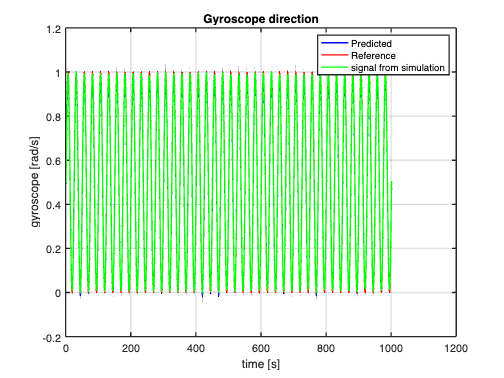

fig1 = figure;
plot(predicted_labels,'b');
hold on;
plot(gyr_ref, 'r');
plot(g_xup,'g');
grid on
xlabel('time [s]');
ylabel('gyroscope [rad/s]');
legend('Predicted','Reference','signal from simulation');
title('Gyroscope direction');
exportgraphics(fig1,'Gyroscope FF direction.png','Resolution',300);

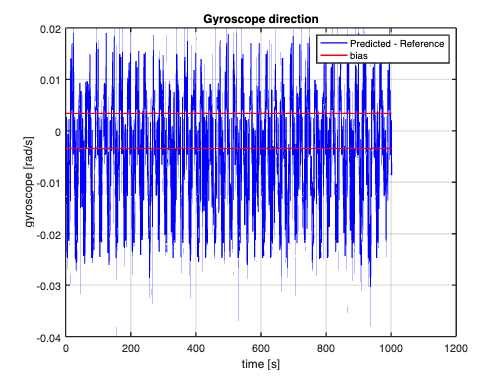


fig2=figure;
delta_g = predicted_labels-gyr_ref;
bias_gyro = repelem(bias_gyro,length(delta_g));
plot(delta_g,'b');
hold on
plot(bias_gyro,'r');
plot(-1*bias_gyro,'r');
grid on
xlabel('time [s]');
ylabel('gyroscope [rad/s]');
legend('Predicted - Reference','bias');
title('Gyroscope direction');
exportgraphics(fig2,'Gyroscope FF direction difference.png','Resolution',300);